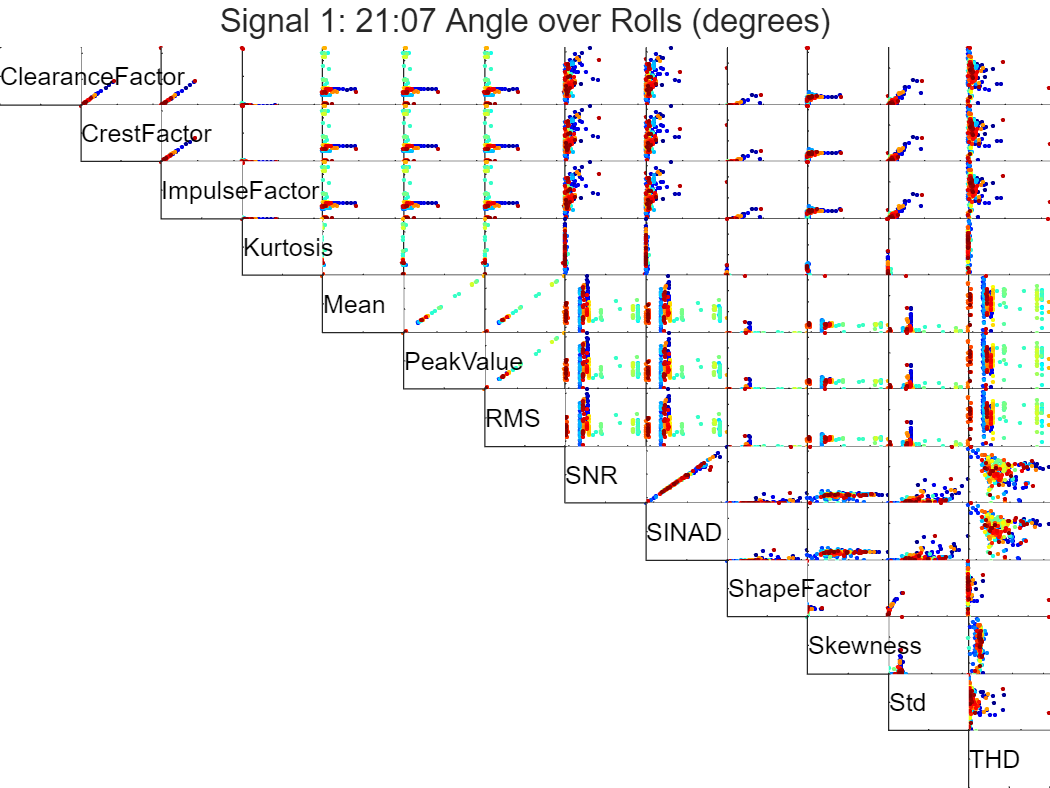

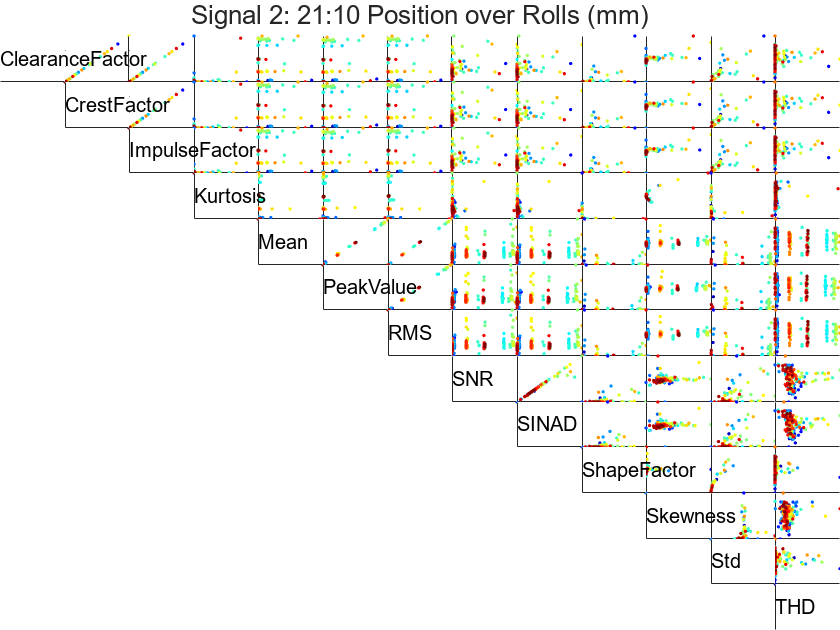

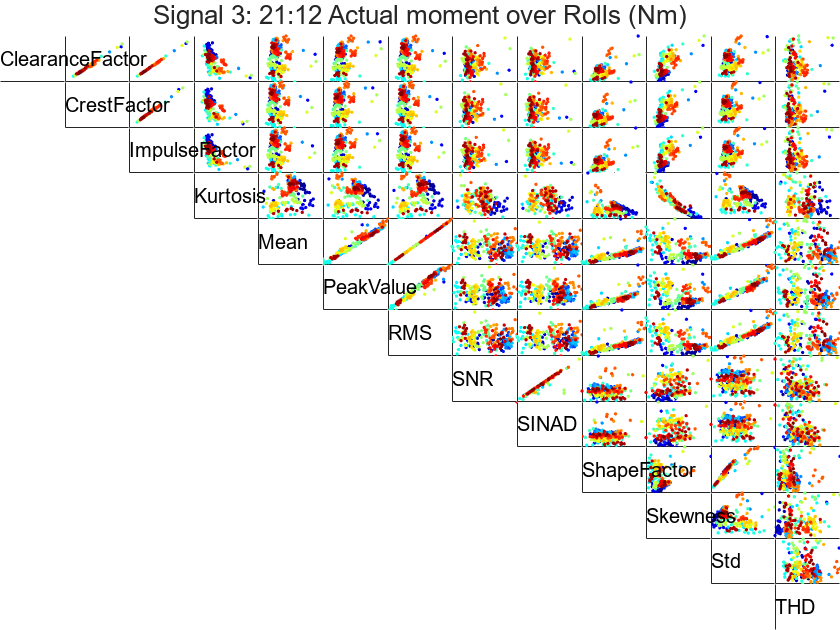

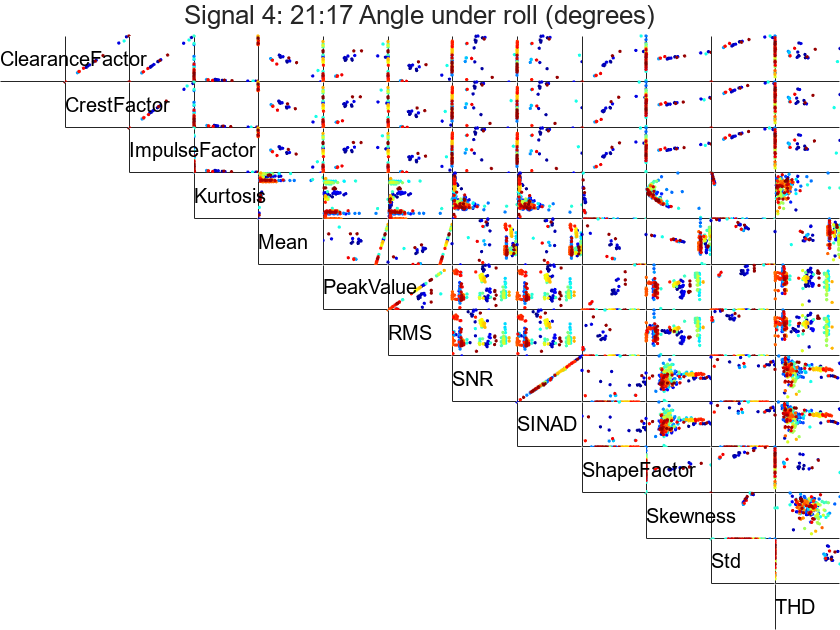

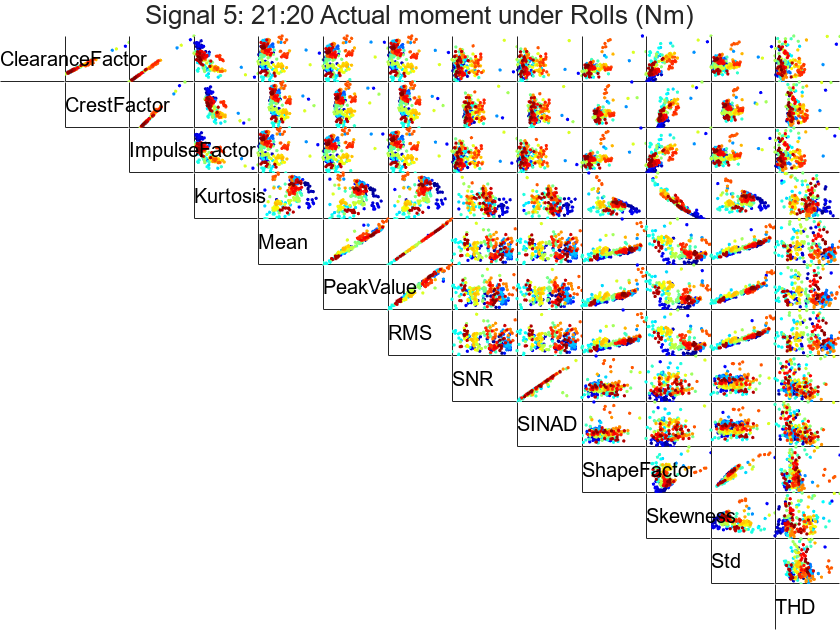

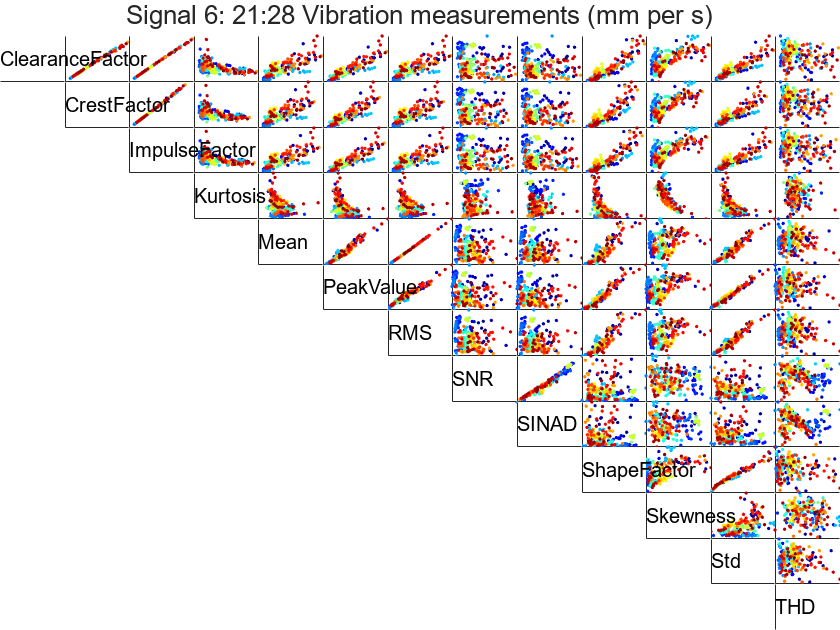

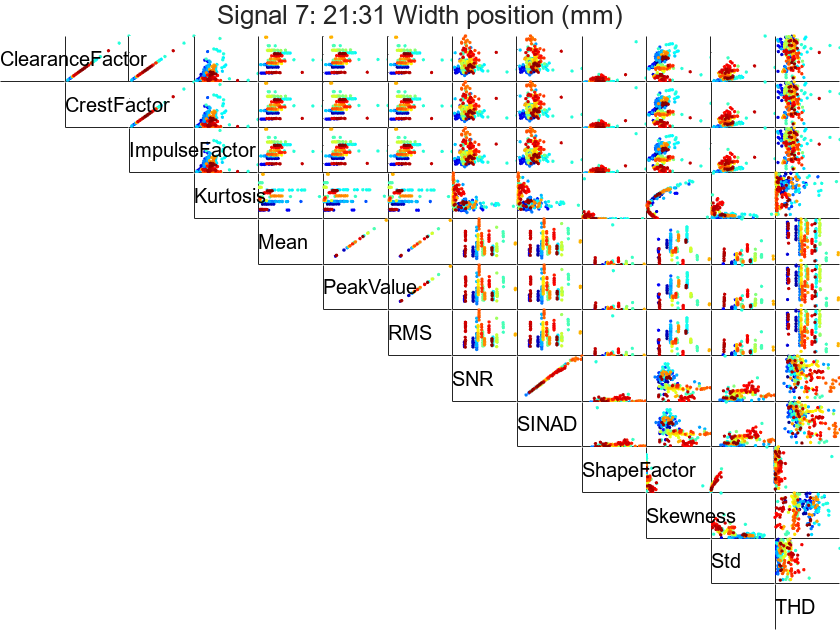

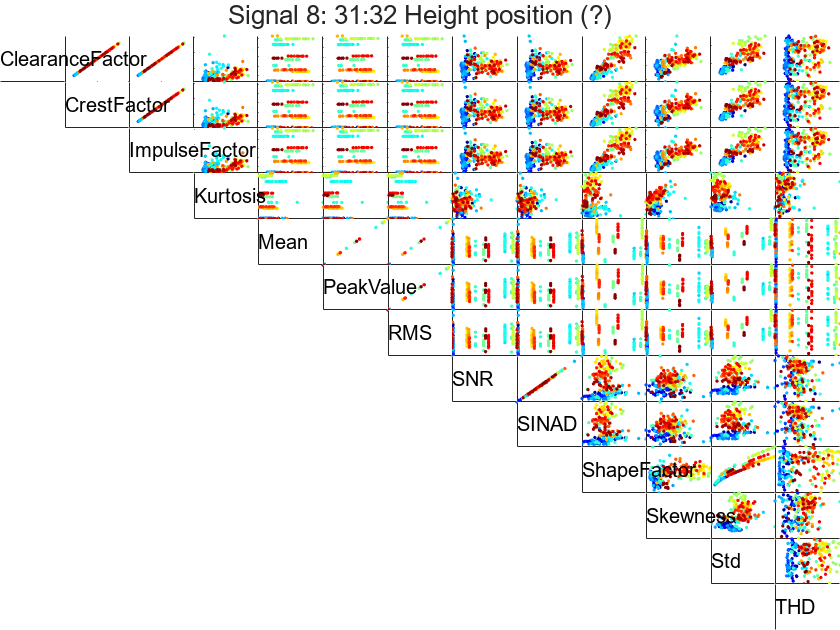

LoadRawData();
LoadFeatures();

for signalNum = 1:numOfSignals
    plotCorrelatedFeaturesAll(signalNum, sensorNames, featureNames, signalName, FeaturesAll);
end

## Function to plot one feature against a different feature

function [] = plotCorrelatedFeaturesAll(signalNum, sensorNames, featureNames, signalName, FeaturesAll)
    figure();
    t = tiledlayout(13,13,'TileSpacing','None', 'Padding','tight');
    title(t, "Signal " + signalNum + ": " + sensorNames(signalNum));
    numpoints = size(FeaturesAll.(signalName(signalNum) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    for i = 1:size(featureNames, 2)
        feature1 = featureNames(i);
        for j = i+1 : size(featureNames, 2)
            nexttile((i-1) * 13 + j);
            feature2 = featureNames(j);
            scatter(FeaturesAll.(signalName(signalNum) + feature1), FeaturesAll.(signalName(signalNum) + feature2), 3, pointidx, 'filled');
            colormap( jet(numpoints) )
            xticklabels({});
            yticklabels({});
        end
    end
    for i = 1:size(featureNames, 2)
        nexttile((i-1) * 13 + i);
        text(0, 0.5, featureNames(i));
        xticklabels({});
        yticklabels({});
    end
end